# Mechanical system before joint

### Write down variables with values

syms J1 J2 J3 J4 beta gamma b k R K_t bm eta

symvars = [J1 J2 J3 J4 beta gamma b k R K_t].';

eta = beta * gamma;
Jt = J3/eta^2 + J2/(beta^2) + J1;

symvalues = [driving_pulley_inertia, driven_pulley_inertia, ...
           harmonic_drive_inertia, head_inertia, timing_belt_ratio, ...
           hd_ratio, mech_filter_b, mech_filter_k Res K_tv]';
tblvals = table(symvars, symvalues);

## Compute state space model with moving rotor

Assume the rotor is able to move

A = [         0           1/eta             -1;
     -k/(eta * Jt) -(b/eta^2 +K_t^2/R)/Jt   b/(eta * Jt);
     k/(J4)    b/(J4 * eta)       -b/(J4)]

$$A = \begin{array}{l} \left(\begin{array}{ccc} 0 & \frac{1}{\beta \,\gamma } & -1\\ -\frac{k}{\beta \,\gamma \,\sigma_{1}} & -\frac{\frac{{K_{t}}^{2}}{R}+\frac{b}{\beta^{2}\,\gamma^{2}}}{\sigma_{1}} & \frac{b}{\beta \,\gamma \,\sigma_{1}}\\ \frac{k}{J_{4}} & \frac{b}{J_{4}\,\beta \,\gamma } & -\frac{b}{J_{4}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=J_{1}+\frac{J_{2}}{\beta^{2}}+\frac{J_{3}}{\beta^{2}\,\gamma^{2}} \end{array}$$

C = [k b/eta -b]

$$C = \left(\begin{array}{ccc} k & \frac{b}{\beta \,\gamma } & -b \end{array}\right)$$

B = [0; K_t/Jt/R; 0]

$$B = \left(\begin{array}{c} 0\\ \frac{K_{t}}{R\,\left(J_{1}+\frac{J_{2}}{\beta^{2}}+\frac{J_{3}}{\beta^{2}\,\gamma^{2}}\right)}\\ 0 \end{array}\right)$$

### Compute transfer function

s = sym('s');
mech_tf_sym = collect(simplify(C / (s*eye(3) - A) * B))

$$mech\_tf\_sym = \frac{\left(J_{4}\,K_{t}\,b\,\beta \,\gamma \right)\,s^{2}+\left(J_{4}\,K_{t}\,\beta \,\gamma \,k\right)\,s}{\left(J_{1}\,J_{4}\,R\,\beta^{2}\,\gamma^{2}+J_{2}\,J_{4}\,R\,\gamma^{2}+J_{3}\,J_{4}\,R\right)\,s^{3}+\left(J_{4}\,{K_{t}}^{2}\,\beta^{2}\,\gamma^{2}+J_{1}\,R\,b\,\beta^{2}\,\gamma^{2}+J_{2}\,R\,b\,\gamma^{2}+J_{3}\,R\,b+J_{4}\,R\,b\right)\,s^{2}+\left(b\,{K_{t}}^{2}\,\beta^{2}\,\gamma^{2}+J_{1}\,R\,k\,\beta^{2}\,\gamma^{2}+J_{2}\,R\,k\,\gamma^{2}+J_{3}\,R\,k+J_{4}\,R\,k\right)\,s+{K_{t}}^{2}\,\beta^{2}\,\gamma^{2}\,k}$$

### Replace symbolic equation with values

mech_tf_sym = subs(mech_tf_sym, tblvals.symvars, tblvals.symvalues);

As = double(subs(A, tblvals.symvars, tblvals.symvalues));
Bs = double(subs(B, tblvals.symvars, tblvals.symvalues));
Cs = double(subs(C, tblvals.symvars, tblvals.symvalues));
Jtv = double(subs(Jt, tblvals.symvars, tblvals.symvalues));

mech_tf = syms2tf(mech_tf_sym)

mech_tf =
 
              2.326e30 s^2 + 2.326e31 s
  --------------------------------------------------
  1.478e26 s^3 + 2.239e30 s^2 + 4.47e31 s + 2.493e32
 
Continuous-time transfer function.



zpk(mech_tf)

ans =
 
            15735 s (s+10)
  -----------------------------------
  (s+1.513e04) (s^2 + 19.99s + 111.5)
 
Continuous-time zero/pole/gain model.



#### Plot step

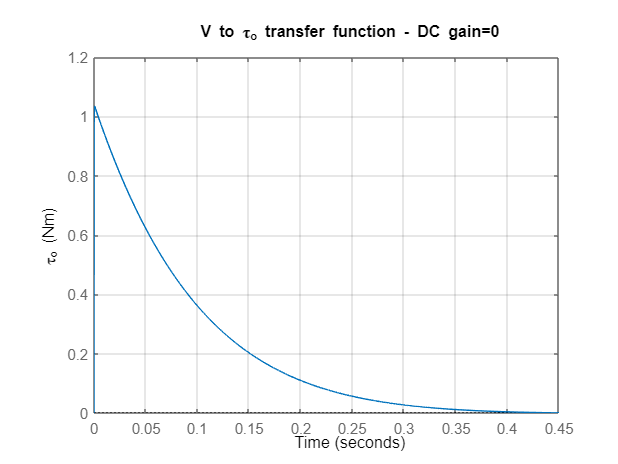

step(mech_tf); grid on; ylabel('\tau_o (Nm)'); 
title('V to \tau_o transfer function - DC gain=' + string(dcgain(mech_tf)))

## Create State space model with fixed rotor

Only two states:


$$x=\left\lbrack \theta_1 \;,\dot{\theta_1 } \right\rbrack$$


where the angle represents the motor rotor.

The electrical dynamics is neglected.

A = [         0           1;
     -k/(eta^2 * Jt) -(b/eta^2 +K_t^2/R)/Jt]

$$A = \left(\begin{array}{cc} 0 & 1\\ -\frac{k}{\beta^{2}\,\gamma^{2}\,\left(J_{1}+\frac{J_{2}}{\beta^{2}}+\frac{J_{3}}{\beta^{2}\,\gamma^{2}}\right)} & -\frac{\frac{{K_{t}}^{2}}{R}+\frac{b}{\beta^{2}\,\gamma^{2}}}{J_{1}+\frac{J_{2}}{\beta^{2}}+\frac{J_{3}}{\beta^{2}\,\gamma^{2}}} \end{array}\right)$$

C = [k/eta b/eta]

$$C = \left(\begin{array}{cc} \frac{k}{\beta \,\gamma } & \frac{b}{\beta \,\gamma } \end{array}\right)$$

B = [0; K_t/Jt/R]

$$B = \left(\begin{array}{c} 0\\ \frac{K_{t}}{R\,\left(J_{1}+\frac{J_{2}}{\beta^{2}}+\frac{J_{3}}{\beta^{2}\,\gamma^{2}}\right)} \end{array}\right)$$


s = sym('s');
mech_tf_sym = collect(simplify(C / (s*eye(2) - A) * B))

$$mech\_tf\_sym = \frac{\left(K_{t}\,b\,\beta \,\gamma \right)\,s+K_{t}\,\beta \,\gamma \,k}{\left(J_{1}\,R\,\beta^{2}\,\gamma^{2}+J_{2}\,R\,\gamma^{2}+J_{3}\,R\right)\,s^{2}+\left({K_{t}}^{2}\,\beta^{2}\,\gamma^{2}+R\,b\right)\,s+R\,k}$$

mech_tf_sym_poles = poles(mech_tf_sym,s)

$$mech\_tf\_sym\_poles = \begin{array}{l} \left(\begin{array}{c} -\frac{R\,b-\sigma_{1}+{K_{t}}^{2}\,\beta^{2}\,\gamma^{2}}{\sigma_{2}}\\ -\frac{\sigma_{1}+R\,b+{K_{t}}^{2}\,\beta^{2}\,\gamma^{2}}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{K_{t}}^{4}\,\beta^{4}\,\gamma^{4}+2\,{K_{t}}^{2}\,R\,b\,\beta^{2}\,\gamma^{2}+R^{2}\,b^{2}-4\,J_{1}\,k\,R^{2}\,\beta^{2}\,\gamma^{2}-4\,J_{2}\,k\,R^{2}\,\gamma^{2}-4\,J_{3}\,k\,R^{2}}\\ \sigma_{2}=2\,\left(J_{1}\,R\,\beta^{2}\,\gamma^{2}+J_{2}\,R\,\gamma^{2}+J_{3}\,R\right) \end{array}$$

### Replace symbolic equation with values

mech_tf_sym = subs(mech_tf_sym, tblvals.symvars, tblvals.symvalues);

As = double(subs(A, tblvals.symvars, tblvals.symvalues));
Bs = double(subs(B, tblvals.symvars, tblvals.symvalues));
Cs = double(subs(C, tblvals.symvars, tblvals.symvalues));
Jtv = double(subs(Jt, tblvals.symvars, tblvals.symvalues));

mech_tf_static = syms2tf(mech_tf_sym)

mech_tf_static =
 
         3.322e29 s + 3.322e30
  ------------------------------------
  2.111e25 s^2 + 3.178e29 s + 2.804e30
 
Continuous-time transfer function.



zpk(mech_tf_static)

ans =
 
       15735 (s+10)
  ----------------------
  (s+1.504e04) (s+8.828)
 
Continuous-time zero/pole/gain model.



#### Plot step

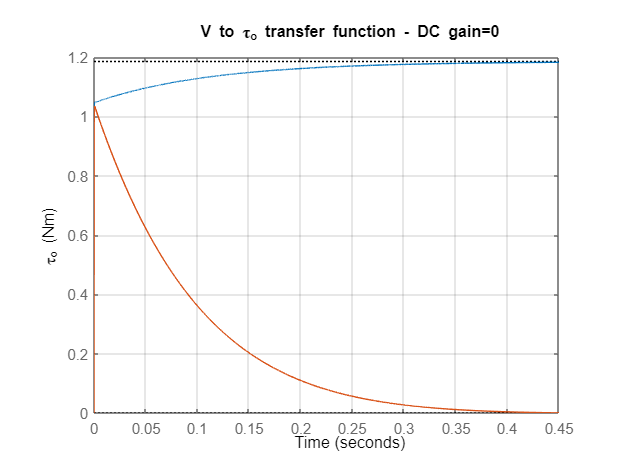

step(mech_tf_static, mech_tf); grid on; ylabel('\tau_o (Nm)'); 
title('V to \tau_o transfer function - DC gain=' + string(dcgain(mech_tf)))